%Least square approximation for exponential functon
%Enter x and y in array form
%y=alpha*e^(beta*x) We will get alpha and beta though least square
%approximation ans=r^2 =(Em-Else)/Else where 𝐸lse =∑(𝑦𝑖 − 𝑎1∗𝑥𝑖 − 𝑎0)^2 and  𝐸m = ∑(𝑦𝑖 − 𝑦̅)^2 where 𝑦̅ =∑ 𝑦𝑖/𝑛  and 𝑖=1 to n
%coefficient of determination, 𝑟^2 is defined as the relative error between 𝐸m and 𝐸lse
x=[1 2 3 4 5 6 7 8];
y=[2.5 7 38 55 61 122 83 143];
ye=log(y);
n=length(x);
format long
a1=(n*sum(x.*ye)-sum(x)*sum(ye))/(n*sum(x.^2)-(sum(x)).^2);
a0=sum(ye)/n-a1*sum(x)/n;
r=(n*sum(x.*ye)-sum(x)*sum(ye))/((sqrt(n*sum(x.^2)-(sum(x))^2))*(sqrt(n*sum(ye.^2)-(sum(ye))^2)));
alpha=exp(a0), beta=a1

alpha =    3.413039270757293


beta =    0.527302082337716


r^2;

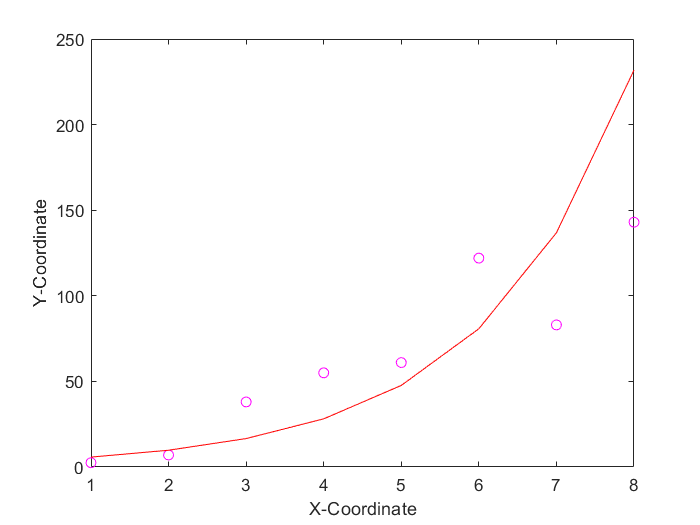

plot(x,y,"mo")
f=alpha*exp(beta*x);
xlabel('X-Coordinate')
ylabel('Y-Coordinate')
hold on
plot(x,f,"-r")
hold off